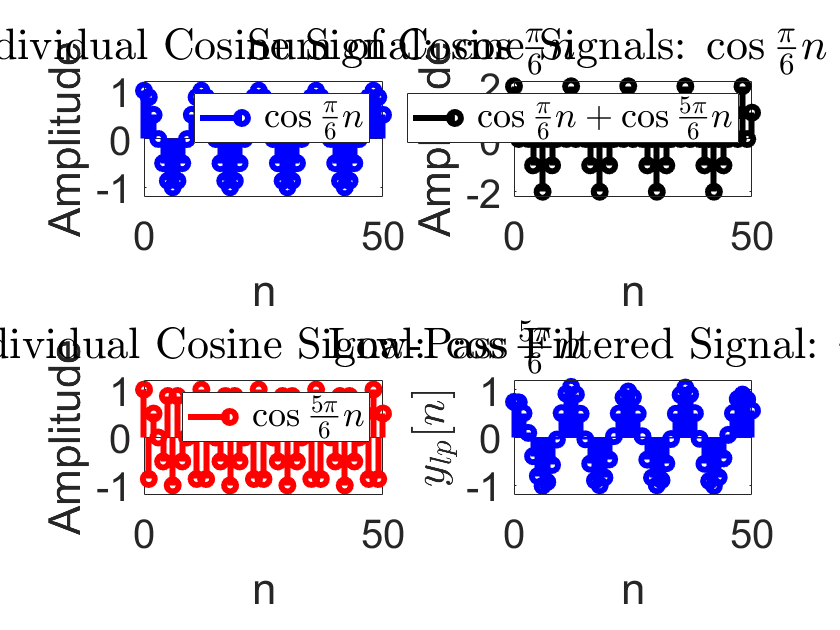

% Creating the x[n] as the sum of two sine signals
n = 0:50;
w1 = pi/6;
w2 = 5*pi/6;
x1 = cos(w1*n);
x2 = cos(w2*n);
x = x1 + x2;
w = -pi:0.001:pi;
X = dtft(n, x, w);
Y_lp = X;
Y_lp(abs(w) > pi/4) = 0;
y_lp = idtft(w, Y_lp, n);

subplot(2,2,1)
stem(n, x1, 'blue', 'linewidth', 3);
set(gca, 'fontsize', 20);
axis([0 50 -1.2 1.2]);
xlabel('n');
ylabel('Amplitude');
legend({'$\cos \frac{\pi}{6}n$'}, 'Interpreter', 'latex');
title('Individual Cosine Signal: $\cos \frac{\pi}{6}n$', 'Interpreter', 'latex');

subplot(2,2,3)
stem(n, x2, 'red', 'linewidth', 3);
set(gca, 'fontsize', 20);
axis([0 50 -1.2 1.2]);
xlabel('n');
ylabel('Amplitude');
legend({'$\cos \frac{5\pi}{6}n$'}, 'Interpreter', 'latex');
title('Individual Cosine Signal: $\cos \frac{5\pi}{6}n$', 'Interpreter', 'latex');

subplot(2,2,2)
stem(n, x, 'black', 'linewidth', 3);
set(gca, 'fontsize', 20);
axis([0 50 -2.2 2.2]);
xlabel('n');
ylabel('Amplitude');
legend({'$\cos \frac{\pi}{6}n+\cos \frac{5\pi}{6}n$'}, 'Interpreter', 'latex');
title('Sum of Cosine Signals: $\cos \frac{\pi}{6}n+\cos \frac{5\pi}{6}n$', 'Interpreter', 'latex');

subplot(2,2,4)
stem(n, real(y_lp), 'blue', 'linewidth', 3);
set(gca, 'fontsize', 20);
axis([0 50 -1.2 1.2]);
xlabel('n');
ylabel('$y_{lp}[n]$', 'Interpreter', 'latex');
title('Low-Pass Filtered Signal: $y_{lp}[n]$', 'Interpreter', 'latex');